## Limpar resíduos de simulação

clear; clc; close all;
 

## Planejador de trajetória 

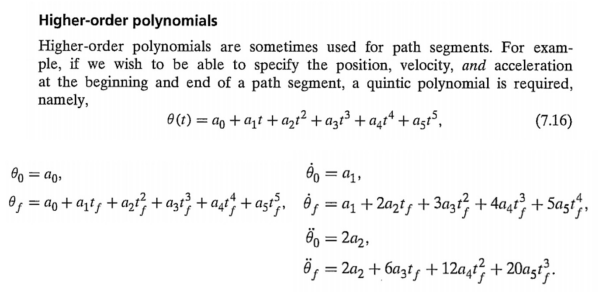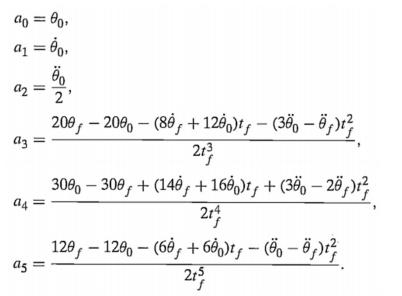

#### Número de voltas

trajConfig.repetitions =3;

#### Formato de trajetória

trajConfig.type = "testxy";

#### Mostrar Trajetória

trajConfig.plot = true;

#### Tempo entre waypoints

trajConfig.segmentTime =10;

#### Angulo de yaw desejado 

trajConfig.yawDesired =0;

#### Planejar trajetória

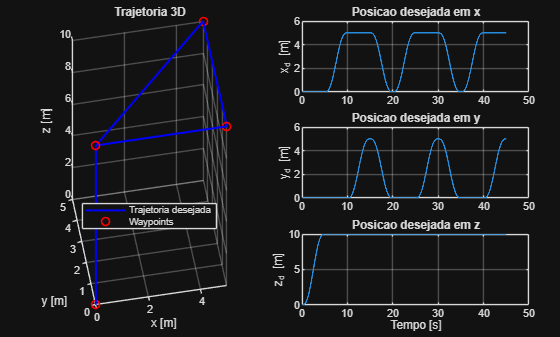

  
traj = TrajectoryPlanner5Order(trajConfig.type, trajConfig.plot, trajConfig.repetitions);

## Modelagem de Quadrirotor

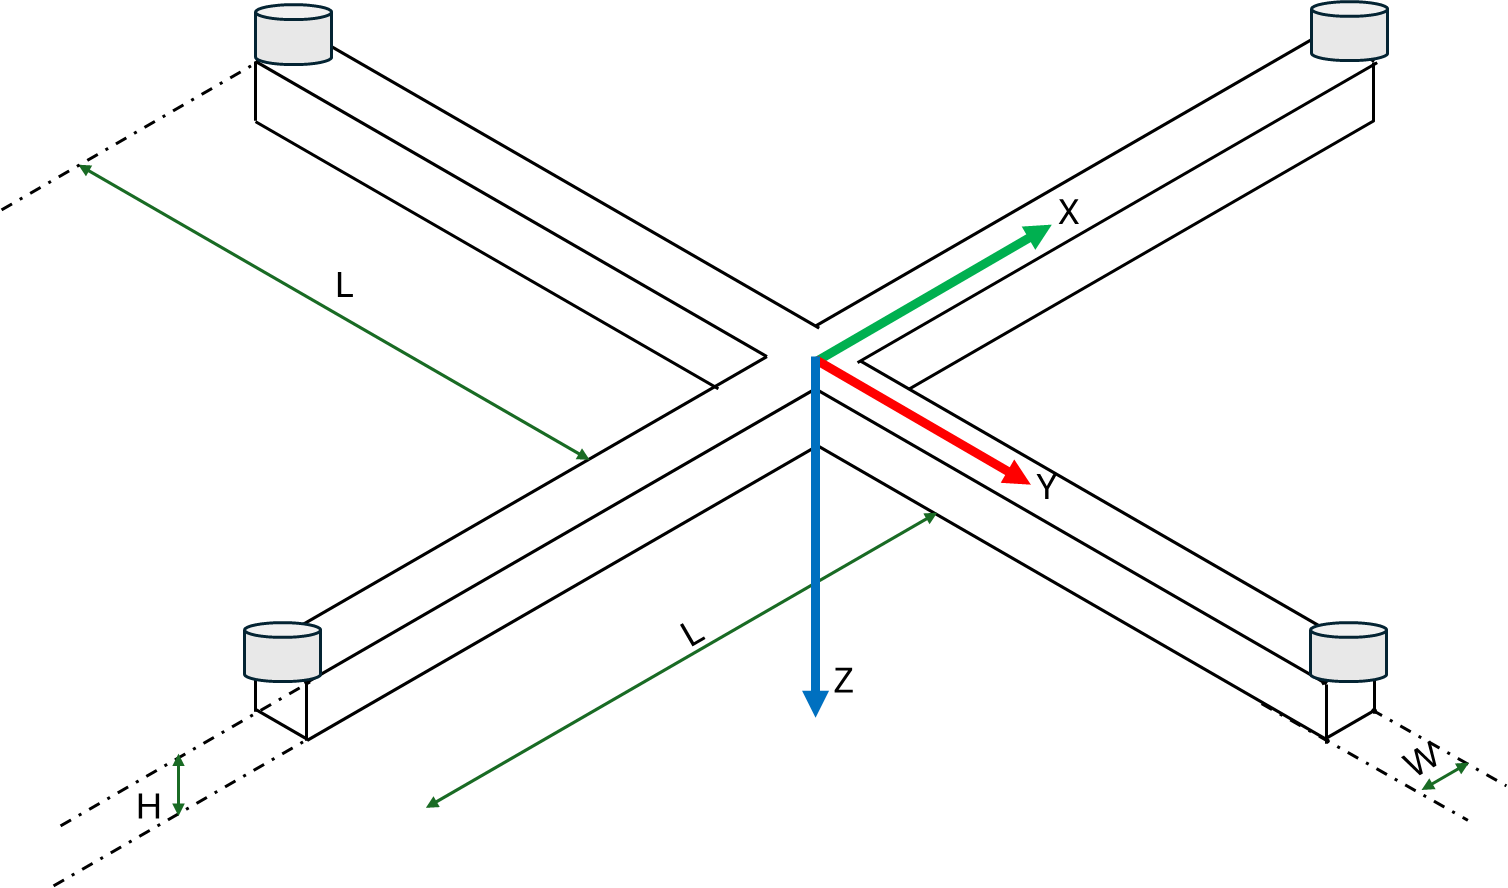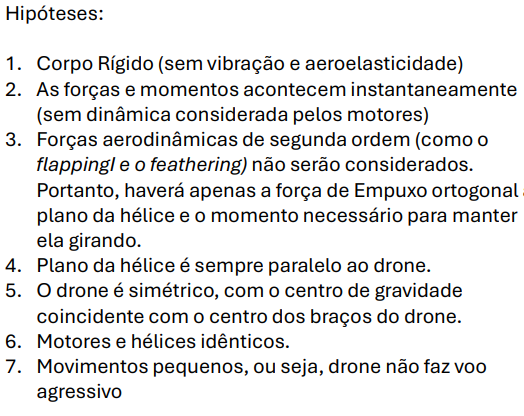

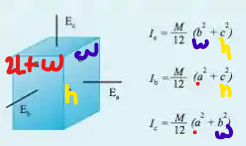

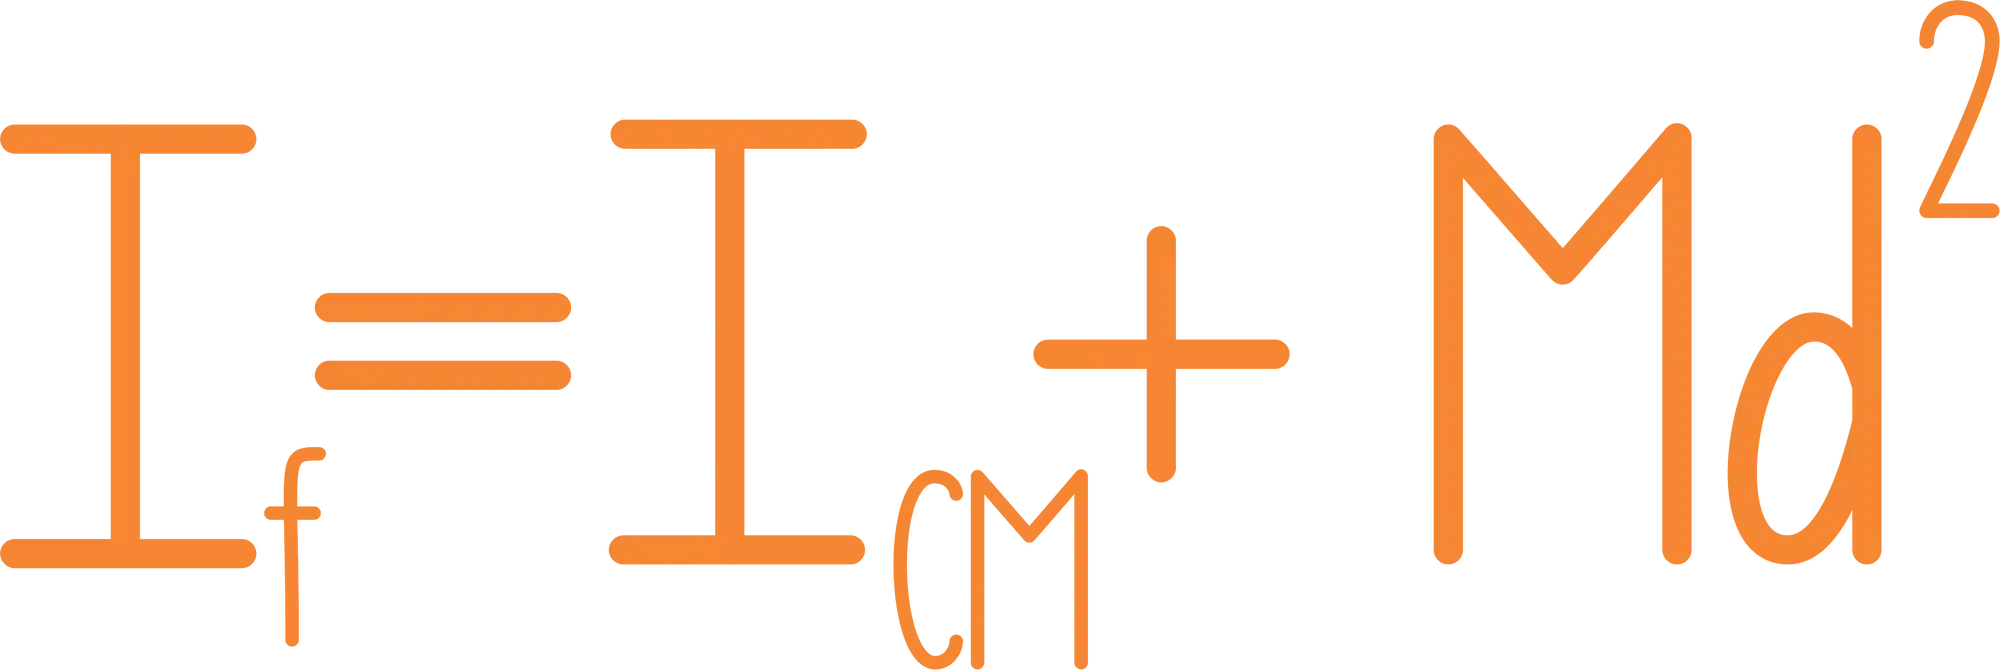

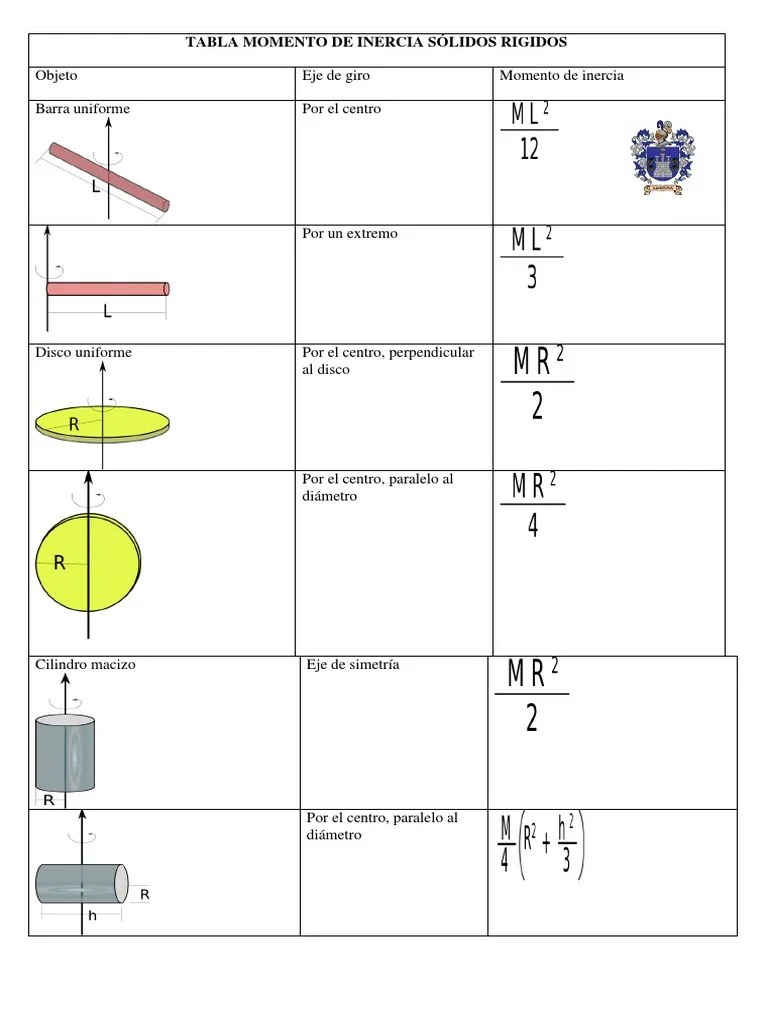

#### Material do drone

quadConfig.material  = "CarbonFiber";

#### Dimensões do Quadrirotor

 L -> comprimento do braco [cm]

W -> largura do braco [cm]

H -> altura/espessura do braco [cm]

L = 20;
W = 5;
H = 1;
quadConfig.droneGeom = [L, W, H];

#### Velocidade de hover

quadConfig.w_hover = 1000;

 
[I_til, quad] = EstimatedQuadParameters(quadConfig.material,quadConfig.droneGeom,quadConfig.w_hover)

I_til =     0.0086         0         0
         0    0.0086         0
         0         0    0.0173


quad = struct with fields:
     material: "CarbonFiber"
      density: 1.6000
      Inertia: [3×3 double]
         mass: 0.9520
    armLength: 0.1250
         Prop: 1.8700e-04
         grav: 9.8100
       k_aero: 2.3348e-06
       k_drag: 2.3348e-07


## Configurações de simulação e condições iniciais

simConfig.Ts = 0.01;
simConfig.tf = 200;
simConfig.motorOmega = 1100*ones(4,1);
simConfig.method = "RK4";


### Definir configuração de simulação

## Configuração de controladores

### Altitude/ Posição

controlConfig.position.type = "PID";
controlConfig.position.updateFreq = 10;
posGains = PositionPIDGains()

posGains = struct with fields:
      P: [1×1 struct]
     PD: [1×1 struct]
    PID: [1×1 struct]


### Atitude

controlConfig.attitude.type = "PD";
controlConfig.attitude.updateFreq = 100;
attGains = AttitudePIDGains()

attGains = struct with fields:
      P: [1×1 struct]
     PD: [1×1 struct]
    PID: [1×1 struct]


### Definir Controladores

###  Loop de simulação

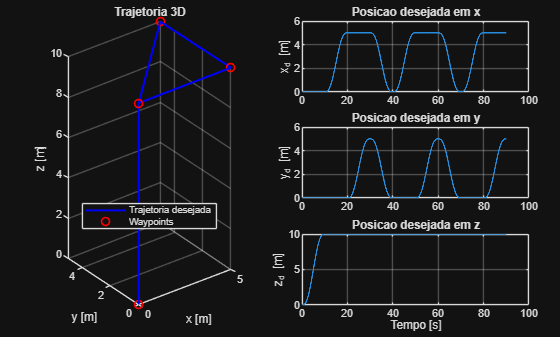

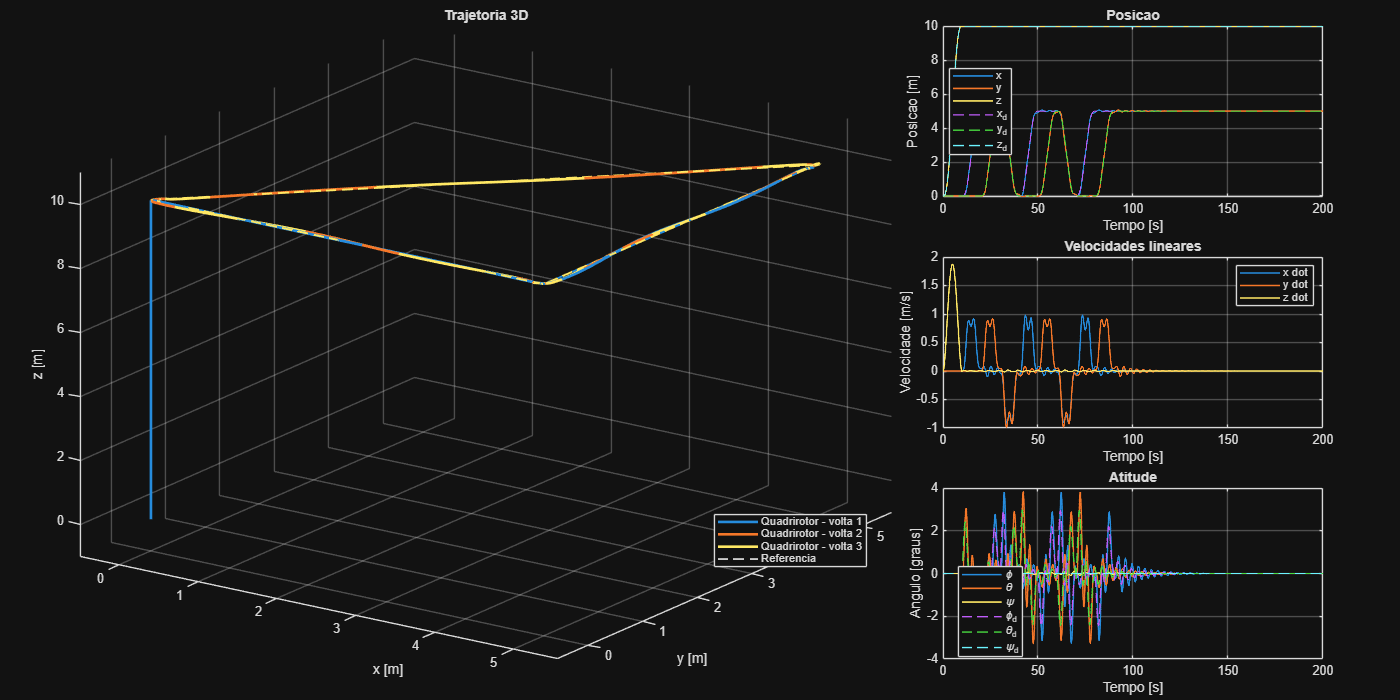

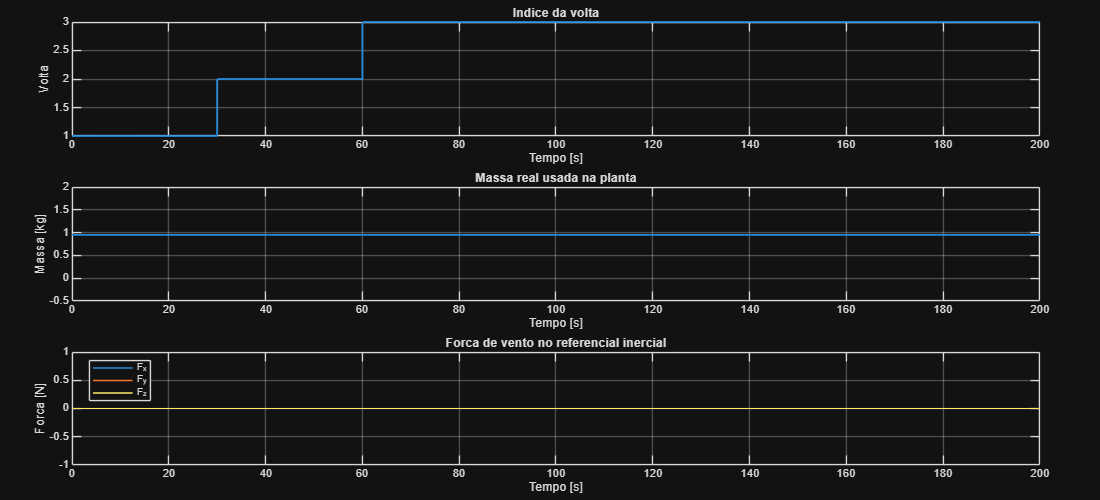

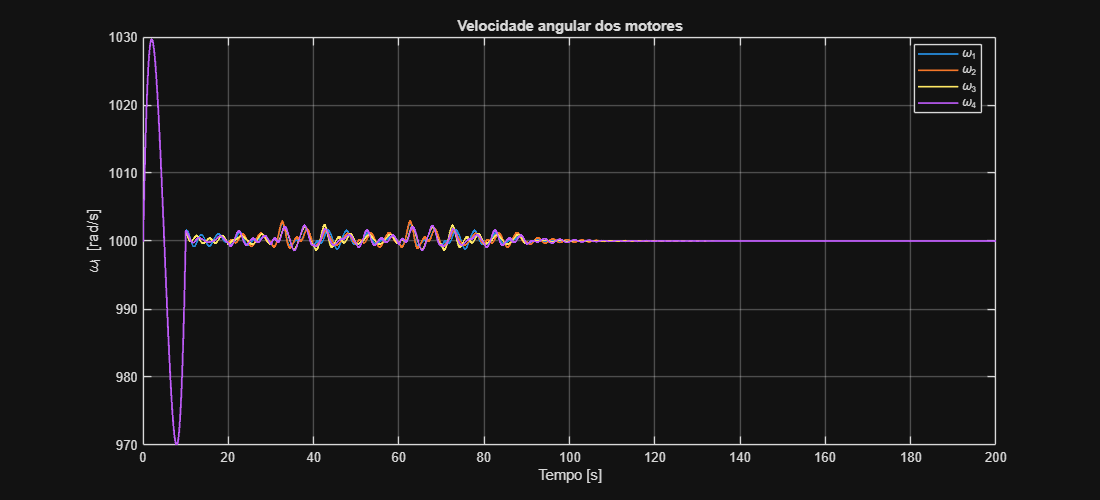

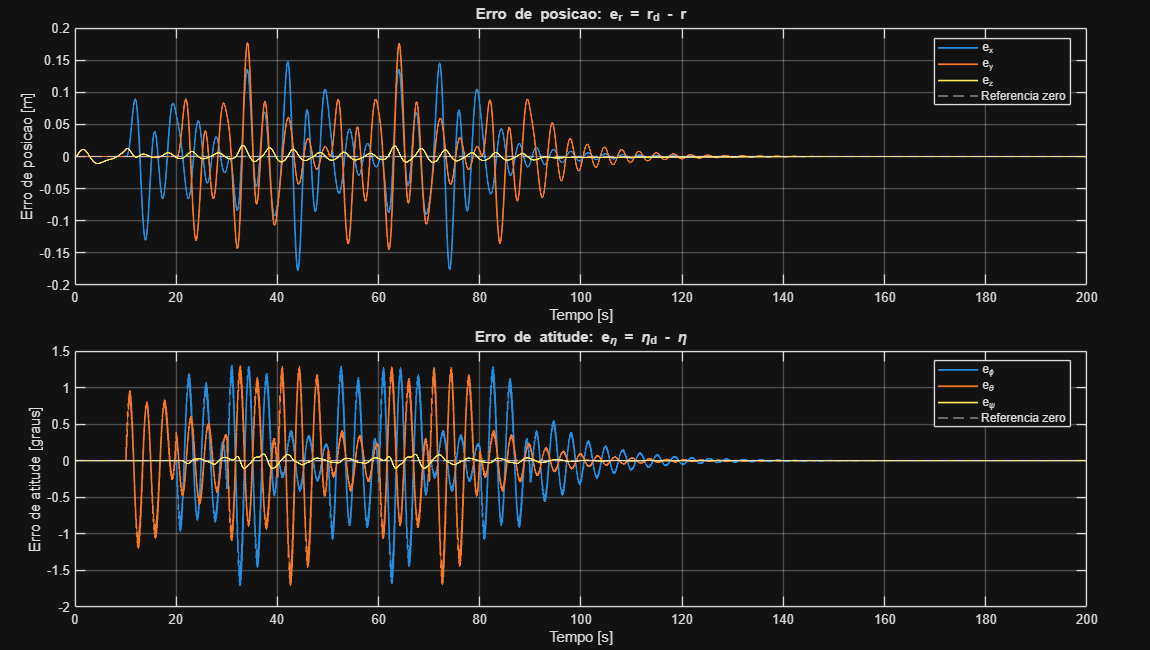

 
sim = ControlledMainLoop(quadConfig,trajConfig,simConfig,controlConfig,true);

### Animação da simulação

 
AnimateQuadrotorSimulation(sim);


--- Animacao do quadrirotor ---
Numero de amostras da simulacao: 20001
Passo entre frames: 10
Numero de frames da animacao: 2001
Numero de voltas detectadas: 3


## Aplicação de disturbios 

%simConfig.flightMode = Trajectory

"TrajectoryOnly"   % só gera/plota a trajetória

ans = "TrajectoryOnly"

"Nominal"          % modelo atual, sem perturbações

ans = "Nominal"

"MassChange"       % muda massa de acordo com a volta

ans = "MassChange"

"Wind"             % aplica força externa de vento

ans = "Wind"

"MassWind"         % muda massa e aplica vento

ans = "MassWind"

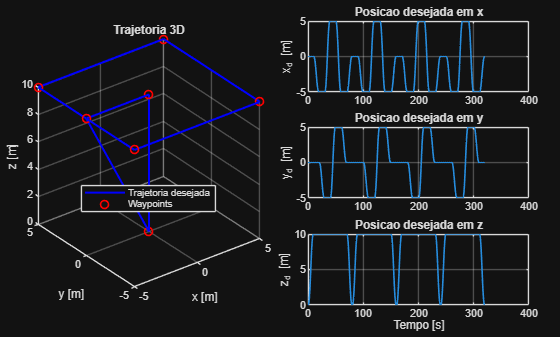

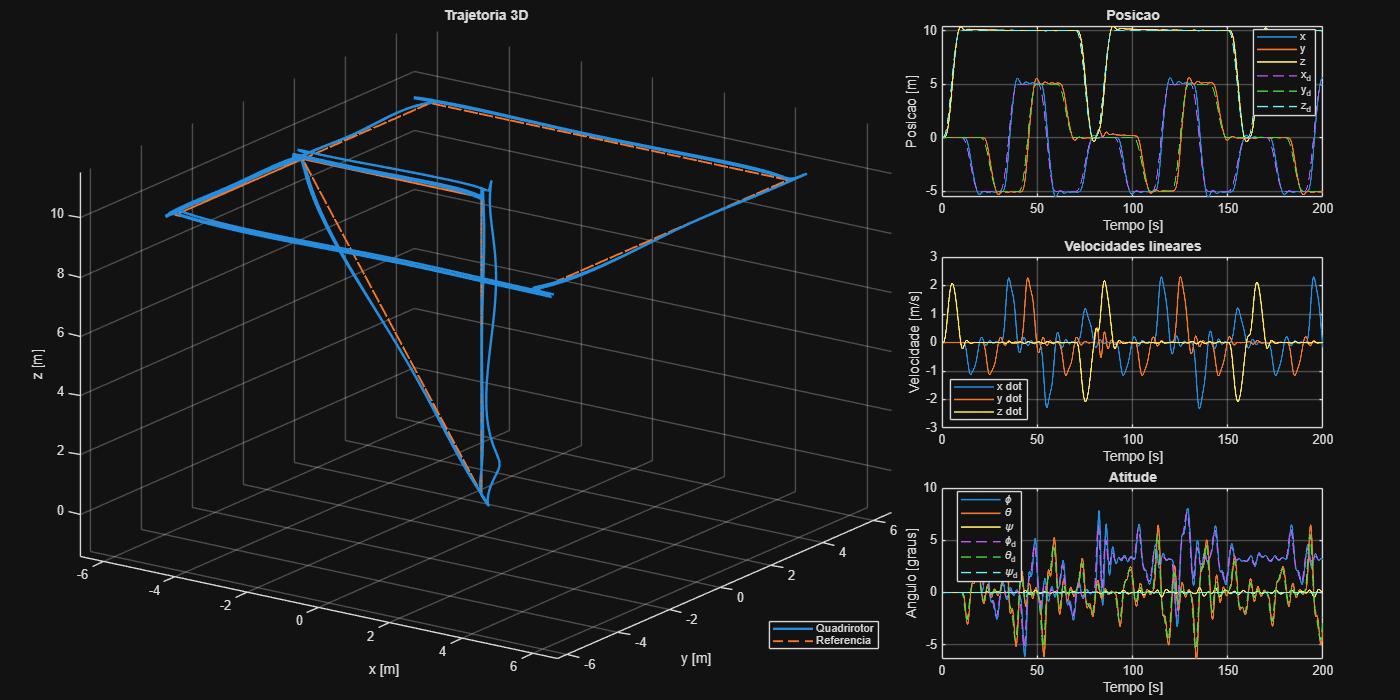

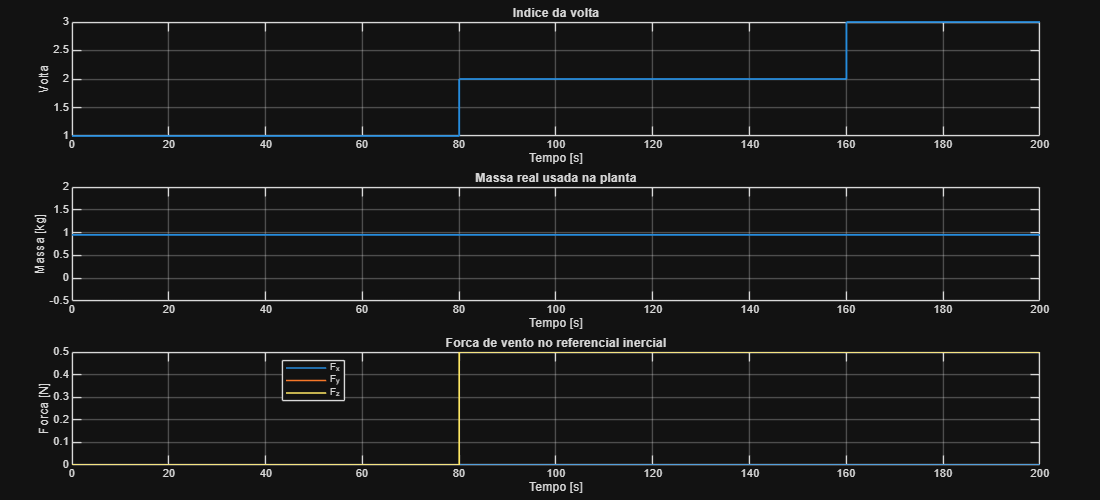


simConfig.flightMode = "Wind";
flightConfig.mode = simConfig.flightMode;

flightConfig.mass.enabled = true;
flightConfig.mass.byLap = [
    1,  0.00;   % volta 1: massa nominal + 0.00 kg
    2, -0.10;  
    3, -0.10    
    4, -0.10    
];

flightConfig.wind.enabled = true;
flightConfig.wind.byLap = [
    1, 0.0, 0.0, 0.0;   % volta 1: sem força externa
    2, 0.0, 0.5, 0.5;  
    3, 0.0, 0.5, 0.5;
    4, 0.2, 0.2, 0.0 
];

sim = ControlledMainLoop( ...
    quadConfig, ...
    trajConfig, ...
    simConfig, ...
    controlConfig, ...
    flightConfig, ...
    true);

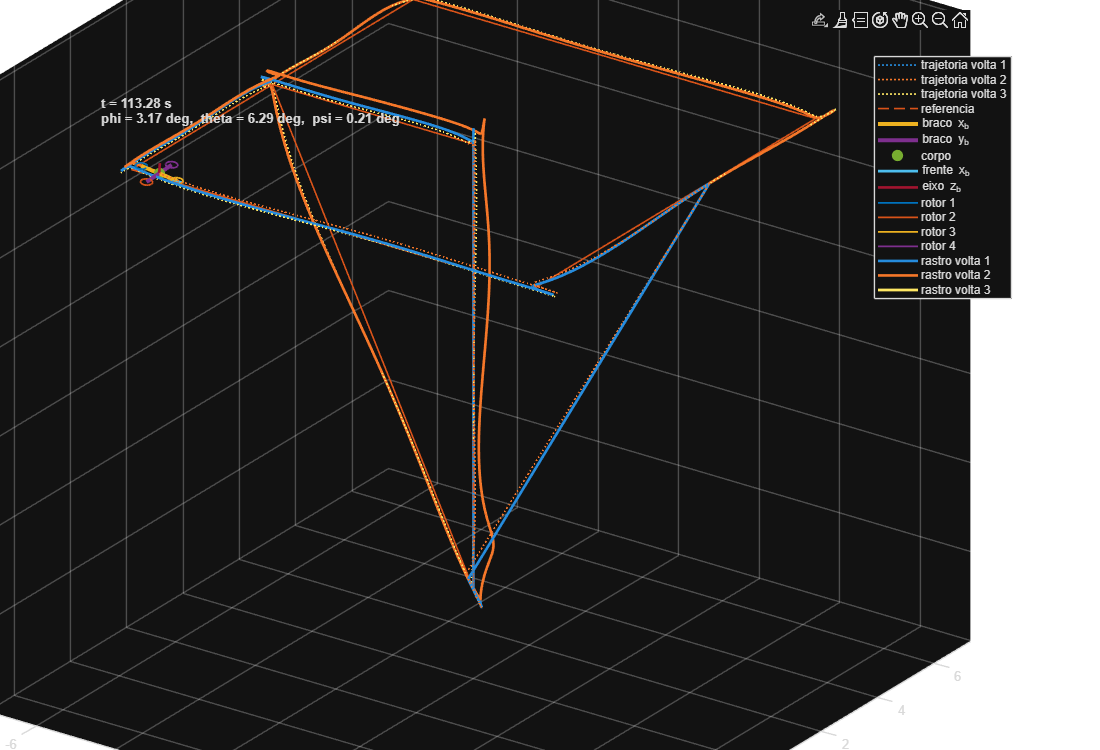

AnimateQuadrotorSimulation(sim);